Reading the message to hide file:

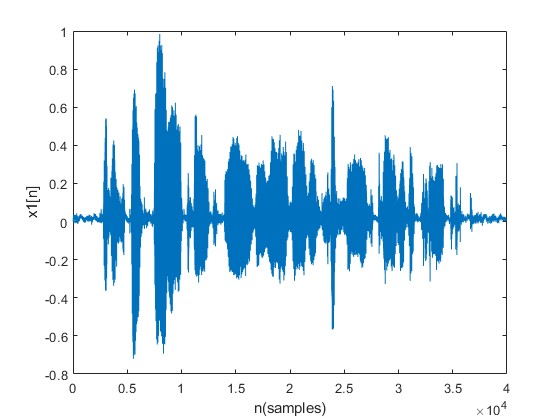

[Message, Fs_Message] = audioread("audio1.wav");
lengthOfMessage = length(Message);
plot(Message)
xlabel("n(samples)")
ylabel("x1[n]")

Reading the Container audio

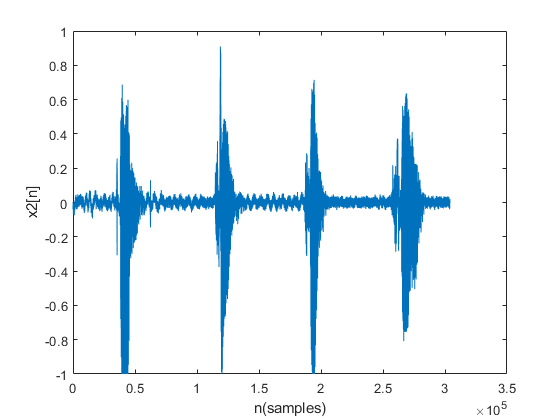

[Container, Fs_Container] = audioread("audio2.wav");
lengthOfContainer = length(Container);
plot(Container)
xlabel("n(samples)")
ylabel("x2[n]")

Plotting the fft output amlitudes with delta fs increments corresponding to 1/ sampling interval = fs/N where N is the total number of samples

For the Message audio

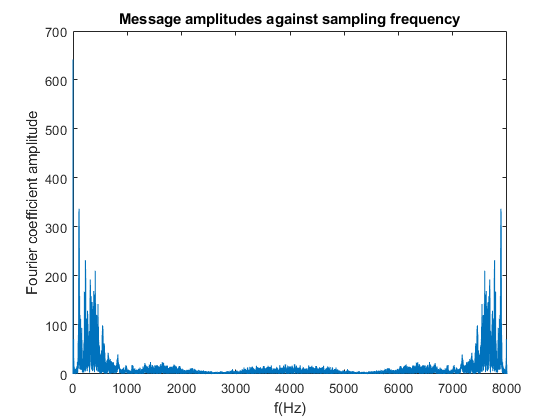

% Get the frequency increments
f_Message = (Fs_Message/lengthOfMessage)  * (0: lengthOfMessage - 1);
fft_Message = abs(fft(Message));
plot(f_Message, fft_Message)
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Message amplitudes against sampling frequency")

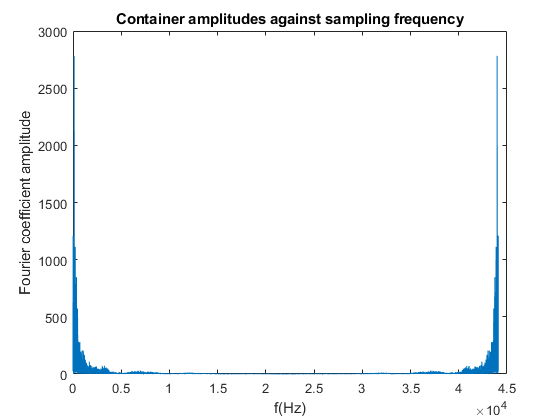

% The same for the container
f_Container = (Fs_Container/lengthOfContainer)  * (0: lengthOfContainer - 1);
fft_Container = abs(fft(Container));
plot(f_Container, fft_Container)
xlabel("f(Hz)")
ylabel("Fourier coefficient amplitude")
title("Container amplitudes against sampling frequency")

Resampling the other signal:

Fs_new = 54e3;
[P, Q] = rat(Fs_new/Fs_Message);
test = resample(Message, P, Q);
[P, Q] = rat(Fs_new/Fs_Container);
Container = resample(Container, P, Q);
lengthOfContainer = length(Container);
% plot the message signal after resamping 
f_testScale = (Fs_Container/length(test)) * (0:length(test) - 1)

f_testScale = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008


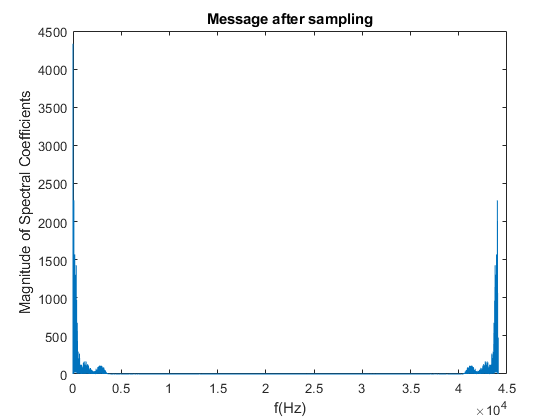

plot(f_testScale, abs(fft(test)))
xlabel("f(Hz)")
ylabel("Magnitude of Spectral Coefficients")
title("Message after sampling")

Adding the two signals:

%length(test) * (1/ Fs_Container)
%testShift= test .* (cos(2* pi * 20000 * (0: length(test) - 1)))'
testTimeScale = (0:length(test) - 1) * (1/Fs_Container)

testTimeScale =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


testcosine = cos(2*pi*(23000) * testTimeScale)

testcosine =     1.0000   -0.9909    0.9636   -0.9187    0.8570   -0.7796    0.6880   -0.5837    0.4688   -0.3454    0.2156   -0.0818   -0.0534    0.1877   -0.3185    0.4435   -0.5604    0.6670   -0.7614    0.8420   -0.9071    0.9556   -0.9866    0.9996   -0.9943    0.9708   -0.9296    0.8713   -0.7971    0.7084   -0.6066    0.4938   -0.3720    0.2433   -0.1102   -0.0249    0.1596   -0.2913    0.4178   -0.5365    0.6455   -0.7427    0.8262   -0.8947    0.9468   -0.9816    0.9984   -0.9969    0.9772   -0.9397


testShift = test .* (0.5 * testcosine')

testShift =    -0.0000
    0.0960
   -0.1989
    0.2739
   -0.2894
    0.2307
   -0.1096
   -0.0486
    0.2126
   -0.2820


testCont = zeros(lengthOfContainer,1)

testCont =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


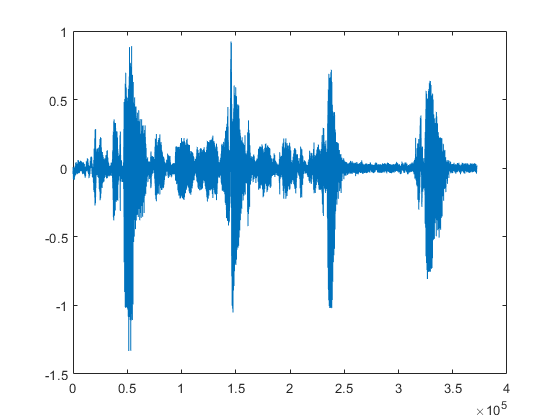

testCont = testCont + Container;
testCont(1: length(test)) = testShift + Container(1: length(test));
plot(testCont)

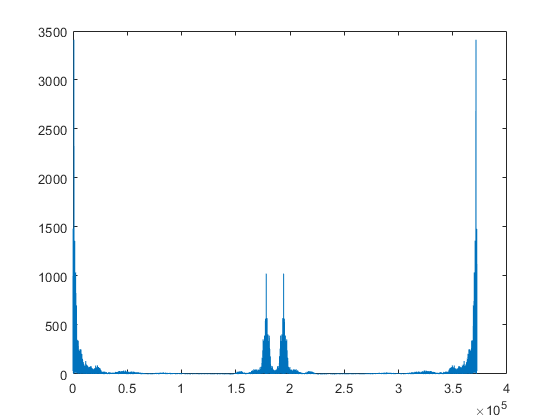

% sound(testCont, Fs_Container)

plot(abs(fft(testCont)))


testTimeScale2 = (0:lengthOfContainer - 1) * (1/Fs_Container)

testTimeScale2 =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


testcosine2 = cos(2*pi*(23000) * testTimeScale2)

testcosine2 =     1.0000   -0.9909    0.9636   -0.9187    0.8570   -0.7796    0.6880   -0.5837    0.4688   -0.3454    0.2156   -0.0818   -0.0534    0.1877   -0.3185    0.4435   -0.5604    0.6670   -0.7614    0.8420   -0.9071    0.9556   -0.9866    0.9996   -0.9943    0.9708   -0.9296    0.8713   -0.7971    0.7084   -0.6066    0.4938   -0.3720    0.2433   -0.1102   -0.0249    0.1596   -0.2913    0.4178   -0.5365    0.6455   -0.7427    0.8262   -0.8947    0.9468   -0.9816    0.9984   -0.9969    0.9772   -0.9397


testCont2 = abs(fft(testCont .* testcosine2'));
% Drawing y[k] before filtering the noise
f_Container2 = (Fs_new/lengthOfContainer) * (0:lengthOfContainer - 1)

f_Container2 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007


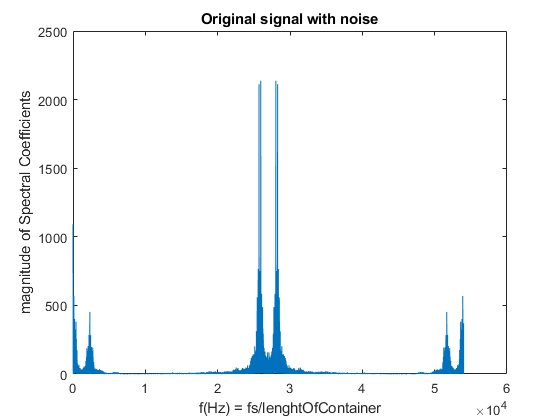

plot(f_Container2, testCont2)
xlabel("f(Hz) = fs/lenghtOfContainer")
ylabel("magnitude of Spectral Coefficients")
title("Original signal with noise")

Removing the noise from the message

testFinal = fft(testCont .* testcosine2') 

testFinal = 	1.0e+03 *

   1.0901 + 0.0000i
  -0.2350 - 0.2841i
   0.0373 - 0.2320i
   0.0679 - 0.0438i
  -0.0434 - 0.0106i
  -0.0257 - 0.0789i
   0.0304 - 0.0613i
   0.0186 - 0.0081i
  -0.0382 - 0.0215i
  -0.0006 - 0.0499i


testFinal(26500:305000) = testFinal(26500:305000) * 0

testFinal = 	1.0e+03 *

   1.0901 + 0.0000i
  -0.2350 - 0.2841i
   0.0373 - 0.2320i
   0.0679 - 0.0438i
  -0.0434 - 0.0106i
  -0.0257 - 0.0789i
   0.0304 - 0.0613i
   0.0186 - 0.0081i
  -0.0382 - 0.0215i
  -0.0006 - 0.0499i


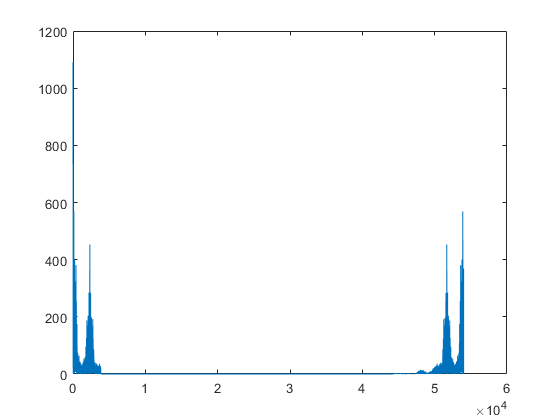

plot(f_Container2,abs(testFinal))

sound(abs(ifft(testFinal)), Fs_Container)